clc;clear all;close all;

fprintf('DB_DATA\r\n');

DB_DATA


cla_data = open_and_importdata('D:\論文\1080911\full\20210415');
fprintf('PCA_DATA\r\n');

PCA_DATA


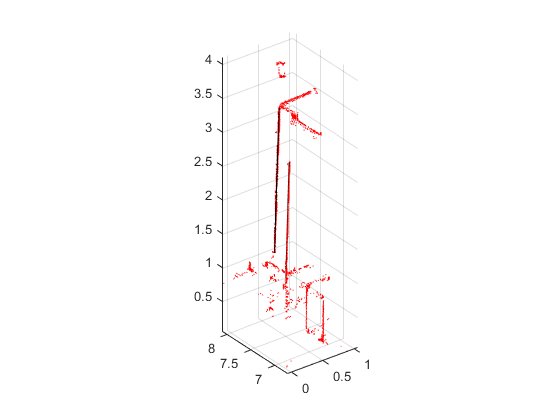

pca_data = open_and_importdata('D:\論文\1080911\full\20210415');

%B1=5,B2=17.5,B4=42.5,B6=67.5,M=130,T6=192.5,T4=217.5,T2=242.5,T1=255

cla_data = cla_data(find(cla_data(:,3)>1),:);

group_num = 1;

figure(1)
scatter3(pca_data(:,1),pca_data(:,2),pca_data(:,3),1,'r','filled');hold on
axis equal

% theta = 90;

std=zeros(4,3);
std(:,3)=0.85; 

B1=zeros(4,3);
B1(:,3)=0.9;

B2=zeros(4,3);
B2(:,3)=1.025;

B4=zeros(4,3);
B4(:,3)=1.275;

B6=zeros(4,3);
B6(:,3)=1.525;

M=zeros(4,3);
M(:,3)=2.15;

T6=zeros(4,3);
T6(:,3)=2.775;

T4=zeros(4,3);
T4(:,3)=3.025;

T2=zeros(4,3);
T2(:,3)=3.275;

T1=zeros(4,3);
T1(:,3)=3.4;

Top=zeros(4,3);
Top(:,3)=3.85;

cla_data_Z = cla_data(find(cla_data(:,4)==3),:);

group_num = max(cla_data_Z(:,5));
group_mean=zeros(group_num,4);
for i=1:group_num
    samegroup = find(cla_data_Z(:,5)==i);
    for j=1:size(samegroup)
        cla_data_Z(samegroup(j),6)=group_mean(i,1);
    end
end

new_group=[];
for i=1:max(cla_data_Z(:,5))
    new_group_num = find(cla_data_Z(:,5)==i);
    if size(new_group_num)~=0
        new_group(i,:) = cla_data_Z(new_group_num(1,1),:);
    end
end
new_group(all(new_group==0,2),:)=[];
for i=1:size(new_group)
    new_group(i,6)=i;
end
new_group_data=[];
for i=1:size(new_group)
    new_group_data = find(cla_data_Z(:,5)==new_group(i,5));
    cla_data_Z(new_group_data(:,1),6)=new_group(i,6);
end

for i=1:1:max(cla_data_Z(:,6))
    group = [];
    group = find(cla_data_Z(:,6)==i);
    
    x = cla_data_Z(group,1);
    y = cla_data_Z(group,2);
    z = cla_data_Z(group,3);
    % 分別擬合兩個二維的曲線，然後統一到一起
    p_zx = polyfit(z,x,2);
    x_out = polyval(p_zx, z);
    
    std(i,1)=polyval(p_zx,std(i,3));
    B1(i,1)=polyval(p_zx,B1(i,3));
    B2(i,1)=polyval(p_zx,B2(i,3));
    B4(i,1)=polyval(p_zx,B4(i,3));
    B6(i,1)=polyval(p_zx,B6(i,3));
    M(i,1)=polyval(p_zx,M(i,3));
    T6(i,1)=polyval(p_zx,T6(i,3));
    T4(i,1)=polyval(p_zx,T4(i,3));
    T2(i,1)=polyval(p_zx,T2(i,3));
    T1(i,1)=polyval(p_zx,T1(i,3));
    Top(i,1)=polyval(p_zx,Top(i,3));
    
    p_zy = polyfit(z,y,2);
    y_out = polyval(p_zy, z);
    
    std(i,2)=polyval(p_zy,std(i,3));
    B1(i,2)=polyval(p_zy,B1(i,3));
    B2(i,2)=polyval(p_zy,B2(i,3));
    B4(i,2)=polyval(p_zy,B4(i,3));
    B6(i,2)=polyval(p_zy,B6(i,3));
    M(i,2)=polyval(p_zy,M(i,3));
    T6(i,2)=polyval(p_zy,T6(i,3));
    T4(i,2)=polyval(p_zy,T4(i,3));
    T2(i,2)=polyval(p_zy,T2(i,3));
    T1(i,2)=polyval(p_zy,T1(i,3));
    Top(i,2)=polyval(p_zy,Top(i,3));
   
  
    % 得出曲線函數 x_out = f(z_out)   z_out = f(y)
%     p_yx_out = polyfit(y_out,x_out,2);
%     x_out_f = polyval(p_yx_out,y_out);
%     
%     std(i,1)=polyval(p_yx_out,std(i,2));
%     B1(i,1)=polyval(p_yx_out,B1(i,2));
%     B2(i,1)=polyval(p_yx_out,B2(i,2));
%     B4(i,1)=polyval(p_yx_out,B4(i,2));
%     B6(i,1)=polyval(p_yx_out,B6(i,2));
%     M(i,1)=polyval(p_yx_out,M(i,2));
%     T6(i,1)=polyval(p_yx_out,T6(i,2));
%     T4(i,1)=polyval(p_yx_out,T4(i,2));
%     T2(i,1)=polyval(p_yx_out,T2(i,2));
%     T1(i,1)=polyval(p_yx_out,T1(i,2));
%     Top(i,1)=polyval(p_yx_out,Top(i,2));
%     
    
    group_num = group_num +1;
    
    figure(1)
    plot3(x_out,y_out,z,'k'); hold on;
    axis equal
end


DATA = [std;B1;B2;B4;B6;M;T6;T4;T2;T1;Top];
% xlswrite('F:\論文\1080919\FULL\20210415\frame_based\C2\二次\C2_0919_DATA2_20210521.xlsx',DATA);
